clear all, close all, clc

## Example 3.1

Given,

N = 10;
t = [1.7, 3.5, 5, 6.5, 8, 9.6, 11, 13, 18, 22]*10^2;  % failure time; hr
S = sum(t);


$$\hat{t} =\frac{1}{N}\sum_1^N t_i$$


t_h = S/N

t_h = 983

For variance,


$$\hat{\sigma} =\frac{1}{N-1}\sum_1^N {{\left(t_i -\hat{t} \right)}}^2$$


A = t - t_h; 
A_sq = A.^2;            % square array
S_sq = sum(A_sq);
sg2_h = S_sq /(N-1)     % variance, hr^2

sg2_h = 4.1140e+05

Now, let's do the following as we know them-

$\hat{\;t} =\hat{\beta} \Gamma {\left(1+\frac{1}{\hat{\alpha} }\right)}$; and ${\hat{\;\sigma \;} }^2 ={\hat{\beta} }^2 {\left[\Gamma {\left(1+\frac{2}{\hat{\alpha} }\right)}-{{\left(\Gamma {\left(1+\frac{1}{\hat{\alpha} }\right)}\right)}}^2 \right]}$

These two equations could be reduced like this-

 ;  

Then, let's make a graphical approach

alf = linspace(1,5,100);
bet1 = t_h ./gamma(1 + 1./alf);
bet2 = sqrt( (sg2_h + t_h^2) ./gamma(1 + 2 ./alf) );

### **Graphical Approach**

Now, let's plot them

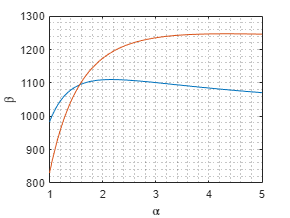

figure()
plot(alf, bet1), grid minor, hold on
plot(alf, bet2), hold off
xlabel('\alpha'); ylabel('\beta')

From the graphical approach, it can be seen that $\alpha$ = 1.58 and $\beta \;$ = 1095. 

### Iterative Approach

Let's find a vector defining by-


$$V=\frac{|\beta_1 -\beta_2 |}{\beta_1 }\;$$


for i = 1:1:length(alf)
    V(i) = abs( bet1(i) - bet2(i) ) /bet1(i);    % value 
end 
c = find(V == min(V));       % finds position of min-value of V

So, let's find what' the value of $\alpha \;$ and $\beta \;$ at vector-position c. Those would be the answers

alf_v = alf(c)

alf_v = 1.5657

bet1_v = bet1(c)

bet1_v = 1.0941e+03

## Example 3.4

Given the follows

f_IC = 0.02;        % failure probab'
f_TS = 0.04;
f_PS = 0.01;

We find-

f_CMS_IC = 1/3;         % failure probab of CMS- given IC
f_CMS_TS = f_CMS_IC; 
f_CMS_PS = f_CMS_IC;

Let's find the failure probability of CMS, from follows-


$$P{\left(H\right)}=\sum_1^N \left.P\left(H\right|E_i \right)P\left(E_i \right)$$


f_CMS = f_CMS_IC*f_IC + f_CMS_TS*f_TS + f_CMS_PS*f_PS

f_CMS = 0.0233

Then, let's use Bayes theorerm for getting $f\left(\mathrm{TS}|\mathrm{CMS}\right)$

$P{\left(E_i |H\right)}=P{\left(E_i \right)}\frac{\left.P\left(H\right|E_i \right)}{P\left(H\right)}$     Or, $\left.P{\left(E_i |H\right)}\;P\left(H\right)=P{\left(E_i \right)}\;P\left(H\right|E_i \right)$

f_TS_CMS = f_TS*f_CMS_TS /f_CMS

f_TS_CMS = 0.5714

### (b)

For revise data from manual

f_CMS_IC = 0.1;         % failure probab of CMS- given PS
f_CMS_TS = 0.15; 
f_CMS_PS = 0.1;

Now, let's find the renewed probability of CMS failure

f_CMS2 = f_CMS_IC*f_IC + f_CMS_TS*f_TS + f_CMS_PS*f_PS

f_CMS2 = 0.0090

Then, the failure-probab' caused by the TS would be-

f_TS_CMS2 = f_TS*f_CMS_TS /f_CMS2

f_TS_CMS2 = 0.6667

## Example 3.5

Done Separately

## Example 3.6

 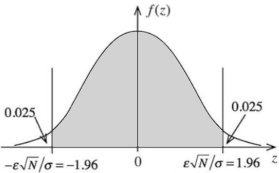     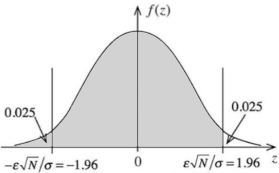 

Figure: alpha value and area for calculating z score.

alf = 0.95;             % cofidence, grey areas
ar = (1 + alf)/2        % area for calculating z-score, 2-tailed CL

ar = 0.9750

z = norminv(ar)         % z-score

z = 1.9600

Given,

x_br = 52;            % sample avg.; ohm
mu_0 = 50;            % manufacturer claim
N = 36;
vr = 9;
sg = sqrt(vr);      % StD

Now, we know $z=\frac{\epsilon \;\;\;}{\sigma \;/\sqrt{\;N}}$

eps = z*sg/sqrt(N)      % distance, at which z lies from sample avg.; ohm

eps = 0.9800

So, there is $\alpha \;$(95%) probability- that the true mean $\mu$ will be within within 0.98 ohm of the sample mean $\bar{x} =52$, so, 

x_up = x_br + eps           % upper value in 95% confidence zone

x_up = 52.9800

x_lw = x_br - eps           % lower value

x_lw = 51.0200

the manufacturer's clame $\mu_0 =50$ could easily be rejected. 

## Example 3.7

### a) 

Here, it is normal distribution of probabilities

alf = 0.95;             % confidence interval
ar = (1 + alf)/2;       % area for calculating z-score
z = norminv(ar)         % dl = z

z = 1.9600

dl = z;                 % limiting value of var z
N = 60;
x_b = 0;

$p\left(z\right)=P\left(\frac{\bar{x\;} -\mu }{\sigma_n }\right)=\alpha \;$, and $z<\delta \;$

Now, reorienting the inequality, we have-

syms p real
sg = sqrt(p*(1-p));       % pu = mu
sg_n = sg/sqrt(N);      % variance of population

Now, reorienting the inequality expresion-

ineq = (x_b - p)^2 *N < dl^2*(p - p^2);
sol = solve(ineq, p, 'ReturnConditions',true);     % 1 for true
% sol.p(1);
res = sol.conditions;
res = vpa(res)

$$res = x<0.060171852142089859526852860821467\wedge 0.0<x$$

**Other Method**

Rewrite the inequality, as equation-

ineq = (x_b - p)^2 *N == dl^2*(p - p^2);
sol = double(solve(ineq,p))

sol =          0
    0.0602


Seeing the results, we can see, the limitting value of p are those shown here. 

### b)

alf = 0.99;              % confidence interval
ar = (1 + alf)/2;        % area for calculating z-score
z = norminv(ar);         % dl = z
dl = z;

N = 169;
x_b = 2/169;

As we have: ${\left(\bar{x} -p\right)}^2 \;N<{\;\delta \;}^2 \left(p-p^2 \right)$

Or, $|\;\frac{\bar{x\;} -p}{\sigma_n \;}\;|\le \delta$;     Or, ${\left(\bar{x\;} -p\right)}^2 \le \delta^2 \;\sigma_n \;$

syms p real
sg = sqrt(p*(1-p));     % variance    
sg_n = sg/sqrt(N);      % pop' variance

ineq = (x_b - p)^2 *N < dl^2*(p - p^2);
% ineq = (x_b - p)^2 < dl^2 *sg_n           % hard to solve
sol = solve(ineq, p, 'ReturnConditions',true);     % 1 for true
sol.p(1);           % not nec'
res = sol.conditions;       % results ITO conditions
res = vpa(res)              % num' approx' of results

$$res = x<0.058237165171608746204174445330172\wedge 0.0023139941186764961448255638324501<x$$

### c)

for 1 sided 99%- we have,

alf = 0.99;       % 1-sided
ar = alf;         % area for calculating z-score
z = norminv(ar);  % dl = z
dl = z

dl = 2.3263


N = 169;
x_b = 2/169;

syms p real

% ineq = (x_b - p)^2*N < dl_2*(p - p^2);
    C1 = (1 + dl^2/N);
    C2 = (2*x_b + dl^2/N);
ineq = C1*p^2 - C2*p + x_b^2 < 0;    
sol = solve(ineq, p, 'ReturnConditions',true);     % 1 for true
sol.p(1);           % not nec'
res = sol.conditions;
res = vpa(res)

$$res = x<0.051319267542852840199197910050958\wedge 0.0026443366124526177398627339769503<x$$

## Example 3.8

alf = 0.99;
N = 169;
k = 2;              % no. of failures

Now, for engineering approach, lets utilize the following-


$$P{\left(o>m\right)}=1-{\left(\sum_0^m \frac{\mu^k }{k!}\right)}\exp \left(-\mu \right)$$


syms p
mu = N*p;
    k = linspace(0,k,k+1);        % vector in k
    fk = factorial(k);
A = (mu).^k ./fk;       % vector
A_S = sum(A)            % sumation term

$$A\_S = \frac{28561\,p^{2}}{2}+169\,p+1$$

Let's build a equation now.

    Lft = 1 - A_S *exp(-mu);
% eqn = Lft == alf;
eqn = 1 - alf == A_S *exp(-mu);

$$eqn = \frac{1}{100}={\mathrm{e}}^{-169\,p}\,\left(\frac{28561\,p^{2}}{2}+169\,p+1\right)$$

Now, for solving, let's plot the equation

sol = vpasolve(eqn, p,0)

 
sol =
 
Empty sym: 0-by-1
 


sol = double(sol)


sol =

  0×1 empty double column vector



## Example 3.9

Given,

alf = 0.99;         % confidence level
n = 2;              % no. of failures
et = 2*(n+1);       % DOF
N = 169;            % no. of trials

So, from inverse cumilitive function, we get $\chi {\;}^2$ value-

ch2 = chi2inv(0.99,et)   % area value, DOF

ch2 = 16.8119

ch = sqrt(ch2);

ch = 4.1002

So, from pdf equation, ge get-

p = ch2 /(2*N)

p = 0.0497